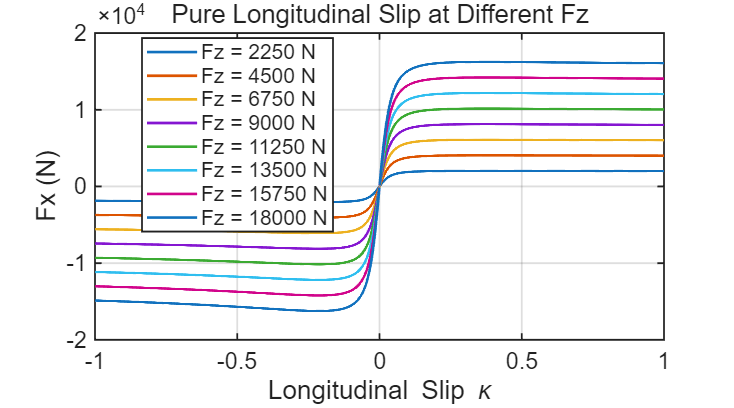

%% --- 绘制轮胎曲线
% 1. 多垂向力下的纯滑移
Fz_vec = [1500,3000,4500,6000,7500,9000,10500,12000]*1.5;
mu = 1;

sx_vec = -1:0.0005:1;         % 给横轴一个显式向量
sy_deg_vec = -15:0.01:15;

Fx_pure = zeros(length(sx_vec), length(Fz_vec));
Fy_pure = zeros(length(sy_deg_vec), length(Fz_vec));

for i = 1:length(Fz_vec)

    Fz = Fz_vec(i);
    
    % --- Pure longitudinal slip
    for j = 1:length(sx_vec)
        Fx_pure(j,i) = tire_force_cal(sx_vec(j), 0, Fz, mu);
    end

    % --- Pure lateral slip
    for j = 1:length(sy_deg_vec)
        sy_rad = sy_deg_vec(j) * pi/180;
        [~, Fy_pure(j,i)] = tire_force_cal(0, sy_rad, Fz, mu);
    end

end



%% 通用绘图设置（强烈推荐）
set(0, 'DefaultLineLineWidth', 1.6);
set(0, 'DefaultAxesFontSize', 14);
set(0, 'DefaultAxesLineWidth', 1.1);
set(0, 'DefaultAxesBox', 'on');      % 外框
set(0, 'DefaultFigureColor', 'w');   % 白底更适合论文
set(0, 'DefaultLegendLocation', 'best');
set(0, 'DefaultLegendFontSize', 12);

% 线条颜色+线型组合
styles = {'-', '-', '-', '-', '-', '-', '-', '-', '-', '-'};
colors = lines(12);

% 图像保存路径（确保存在）
savePath = './plots/';
if ~exist(savePath, 'dir')
    mkdir(savePath);
end

%% --- 绘制 Fx Pure Slip ---
figure('Position',[200 200 900 500]); hold on; grid on;

for i = 1:length(Fz_vec)
    plot(sx_vec, Fx_pure(:,i), ...
        'Color', colors(i,:), ...
        'LineStyle', styles{i});
end

xlabel('Longitudinal Slip \kappa');
ylabel('Fx (N)');
title('Pure Longitudinal Slip at Different Fz');
legend(arrayfun(@(fz)sprintf('Fz = %d N', fz), Fz_vec, 'UniformOutput', false));

% 高分辨率输出
exportgraphics(gcf, fullfile(savePath, 'Fx_pure.png'), 'Resolution',600);

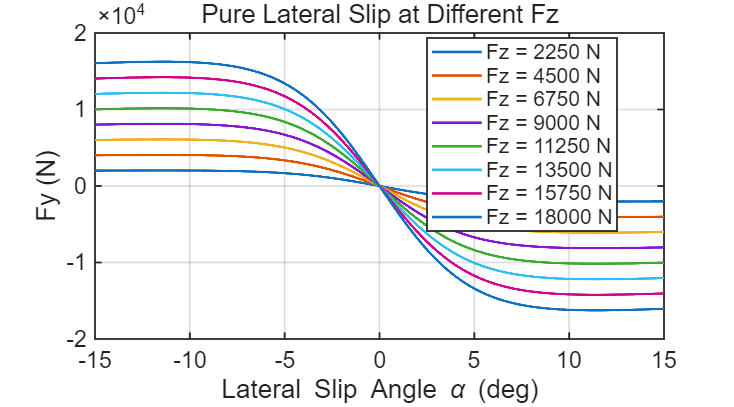



%% --- 绘制 Fy Pure Slip ---
figure('Position',[200 200 900 500]); hold on; grid on;

for i = 1:length(Fz_vec)
    plot(sy_deg_vec, Fy_pure(:,i), ...
        'Color', colors(i,:), ...
        'LineStyle', styles{i});
end

xlabel('Lateral Slip Angle \alpha (deg)');
ylabel('Fy (N)');
title('Pure Lateral Slip at Different Fz');
legend(arrayfun(@(fz)sprintf('Fz = %d N', fz), Fz_vec, 'UniformOutput', false));

exportgraphics(gcf, fullfile(savePath, 'Fy_pure.png'), 'Resolution',600);

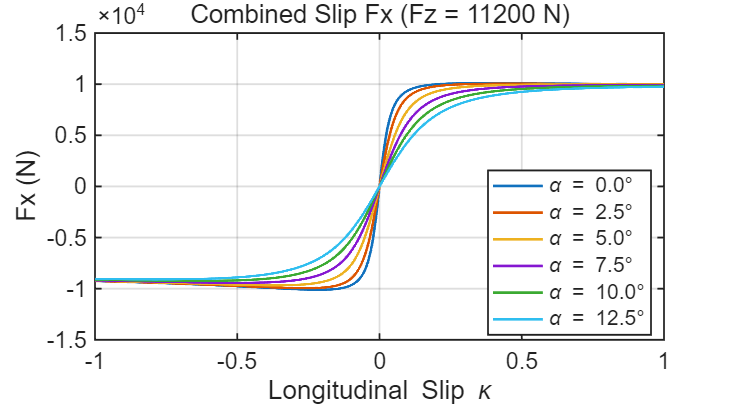








%% ------- 2. 单垂向力下的组合滑移 -------
mu = 1;
Fz = 11200;

sx_cb_vec = -1:0.0005:1;
sy_deg_cb_vec = -15:0.1:15;

Fx_cb = zeros(length(sx_cb_vec), 6);
Fy_cb = zeros(length(sy_deg_cb_vec), 6);

for i = 1:6

    sy_const = (i-1)*2.5 * pi/180;  % const sy
    sx_const = (i-1)*0.1;           % const sx

    % --- Fx_combined
    for j = 1:length(sx_cb_vec)
        Fx_cb(j,i) = tire_force_cal(sx_cb_vec(j), sy_const, Fz, mu);
    end

    % --- Fy_combined
    for j = 1:length(sy_deg_cb_vec)
        sy_rad = sy_deg_cb_vec(j) * pi/180;
        [~, Fy_cb(j,i)] = tire_force_cal(sx_const, sy_rad, Fz, mu);
    end

end

%% --- 绘制 Fx Combined Slip ---
figure('Position',[200 200 900 500]); hold on; grid on;

for i = 1:6
    plot(sx_cb_vec, Fx_cb(:,i), ...
        'Color', colors(i,:), ...
        'LineStyle', styles{i});
end

xlabel('Longitudinal Slip \kappa');
ylabel('Fx (N)');
title(sprintf('Combined Slip Fx (Fz = %d N)', Fz));
legend(arrayfun(@(ang)sprintf('\\alpha = %.1f°', ang), 0:2.5:12.5, 'UniformOutput', false));

exportgraphics(gcf, fullfile(savePath, 'Fx_combined.png'), 'Resolution',600);

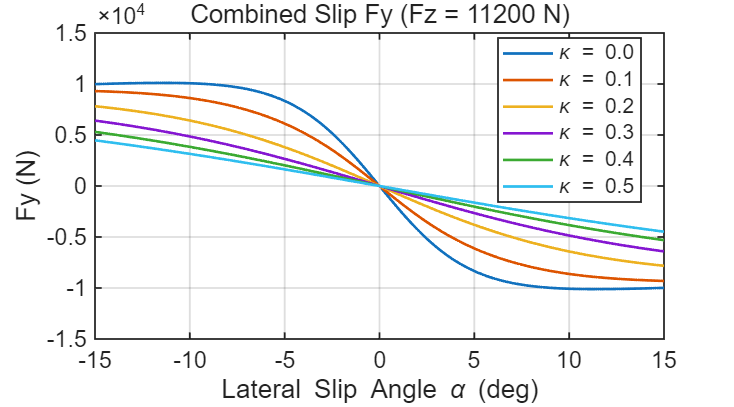



%% --- 绘制 Fy Combined Slip ---
figure('Position',[200 200 900 500]); hold on; grid on;

for i = 1:6
    plot(sy_deg_cb_vec, Fy_cb(:,i), ...
        'Color', colors(i,:), ...
        'LineStyle', styles{i});
end

xlabel('Lateral Slip Angle \alpha (deg)');
ylabel('Fy (N)');
title(sprintf('Combined Slip Fy (Fz = %d N)', Fz));
legend(arrayfun(@(sx)sprintf('\\kappa = %.1f', sx), 0:0.1:0.5, 'UniformOutput', false));

exportgraphics(gcf, fullfile(savePath, 'Fy_combined.png'), 'Resolution',600);

function [Fx,Fy] = tire_force_cal(kappa, alfa, Fz, miu)

% kappa-纵向滑移率; alfa-侧偏角; miu-附着系数; Fz-垂向载荷 

% 组合滑移率计算 （combined slip theory）
sigma_x = -kappa./(1+kappa);
sigma_y = tan(alfa)./(1+kappa);
sigma_total = sqrt(sigma_x.^2+sigma_y.^2);

% 归一化滑移值计算 （normalized slip）
kappa_max = 0.14;   % 纵向力峰值时滑移率，按名义载荷结果取14%
alfa_max = 0.1484;  % 侧向力峰值时的质心侧偏角，按名义仿真结果取8.5deg
sigma_xmax = -kappa_max/(1+kappa_max);
sigma_ymax = tan(alfa_max)/(1+kappa_max);

sigma_xs = sigma_x/sigma_xmax;
sigma_ys = sigma_y/sigma_ymax;
sigma_ts = sqrt(sigma_xs.^2+sigma_ys.^2);

% 等效纵、侧向滑移率
kappa_s = -(sigma_ts*sigma_xmax.*sign(sigma_x))./(1+abs(sigma_ts*sigma_xmax.*sign(sigma_x)));
alfa_s = atan(sigma_ts*sigma_ymax.*sign(sigma_y));

% 拟合的纵、侧向轮胎力魔术公式
% Fx0 = miu*Fz.*sin(1.89*atan(15.5*(1-0.9673)*(kappa_s./miu)+0.9673*atan(15.5*(kappa_s./miu))));
% Fy0 = miu*Fz.*sin(2.206*atan(8.017*(1-1.004)*(alfa_s./miu)+1.004*atan(8.017*(alfa_s./miu))));
    
    % 轮胎 265/75 R16
    Fx0 = miu*Fz.*0.9022.*sin(1.399*atan(18.01*(1-0.698)*(kappa_s./miu)+0.698*atan(18.01*(kappa_s./miu))));
    Fy0 = miu*Fz.*0.9028.*sin(2.243*atan(5.711*(1-1.023)*(alfa_s./miu)+1.023*atan(5.711*(alfa_s./miu))));

Fx0 = abs(Fx0);
Fy0 = abs(Fy0);

epsilon = min(sigma_ts,1);
Fx0s = Fx0 - epsilon.*(Fx0-Fy0).*(sigma_ys./sigma_ts).^2;
Fy0s = Fy0 - epsilon.*(Fy0-Fx0).*(sigma_xs./sigma_ts).^2;

% 下述即设置 q1=0 时的轮胎力计算公式
% Fx = Fx0s.*sigma_xs./sigma_ts.*sign(sigma_xs);
Fx = Fx0s.*sigma_xs./sigma_ts;
Fy =-Fy0s.*sigma_ys./sigma_ts;

end